# Lecture 12 Computational Imaging - Computed Tomography

## 1. Introduction

Computational imaging refers to a broad set of techniques where image aquisition is combined with post-processing to produce a desired image or extract specific information from a scene. Instead of relying soley on traditional optical components (like lenses and mirrors) to form an image, computational imaging uses algorithms and computations to enhance, modify, or recover the objects of interest.

The image acquisition can usually be mathematically modeled as a transform:


$$g^{\left(v\right)} =h^{\left(v\right)} \left\lbrace f\right\rbrace$$


Where $f$ is the object of interest.  $h$ is an operator, which models the image formation process, can be either linear or non-linear. $v\;$is a parameter of the imaging system and $g$ is the measurement. For conventional point-to-point (localized) imaging systems, e.g., lens imaging, $h$ is a simple convolution kernel and $q$ is the blurry image we measured.

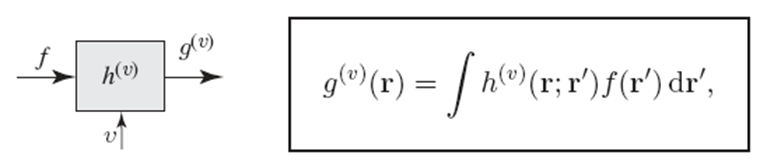

**ILL. 1.1 Computational imaging requires the modeling of the image forming process (known as the forward model)**

Computational imaging is a broad topic, so in this chapter, we limit ourselves to tomographic imaging, one of the most widely used computational imaging techniques.

### 1.1 Localized imaging vs. computational imaging

In **localized imaging, **each measurement is sensitive to a single point, or a small patch, within the object, so that the object distribution may be constructed by taking measurements at a set of points filling the object space.

In **tomographic imaging, **by contrast, the scanned spot is an extended region of some shape, so that each measurement recieves contributions from many points distributed within that spot. Each measurement is then not, by itself, sufficient to discern the individual contributions of the many points within its scanned spot. Nevertheless, by using multiple measurements with overlapping or crossing scanned spots, a set of measurements can be sufficient to figure out the overall object distribution by use of the computational methods.

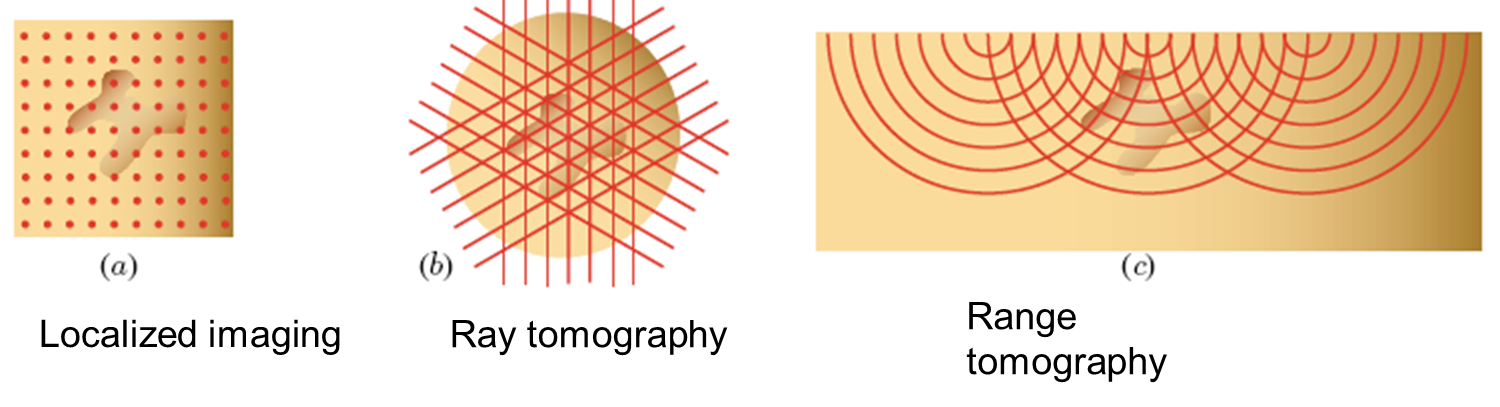

**ILL. 1.2*** Localized imaging vs computational imaging*

## 2. Theory of computed tomography

### 2.1 Ray tomography and projection

Ray tomogrpahy is a technique for probing the absorption coefficient of an object by use of multiple rays (for example, X-rays). Each ray is assumed to travel through the object without changing its direction. The intensity of the ray at the exit depends on the total absorption along the ray path. If $\alpha \left(\mathrm{r}\right)$is the absorption coefficient at position $\mathrm{r}$, then the ray transmitance


$$T=\exp \left\lbrack -\int_{\textrm{ray}} \alpha \left(\mathrm{r}\right)\;\textrm{dl}\right\rbrack$$


Attenuation measurement $\gets$ physical property:


$$-\ln \left(T\right)=\int_{\textrm{ray}} \alpha \left(\mathrm{r}\right)\;\textrm{dl}$$


The integral is called the *sum ray *or the *projection. *Projections along multiple rays in multiple directions are measured and the distribution of the absorption coefficient $\alpha \left(\mathrm{r}\right)$ is to be estimated. A principal application of ray tomography is X-ray computed tomography (CT).

Projection $\gets$ Object (abstract):

$g_{\textrm{ray}} =\int_{\textrm{ray}} f\left(\mathrm{r}\right)\;\textrm{dl}$,

where $g_{\textrm{ray}}$ corresponds to $-\ln \left(T\right)$ and $f\left(\mathrm{r}\right)$ corresponds to $\alpha \left(\mathrm{r}\right)$.

$g^{\left(v\right)} \left(s\right)=\int h^{\left(v\right)} \left(s,\mathrm{r}\right)f\left(\mathrm{r}\right)\;\textrm{dr}$,

where $g^{\left(v\right)} \left(s\right)$ is the projection along the $v$ direction and $h^{\left(v\right)} \left(s,\mathrm{r}\right)$ is a line delta function of $\mathrm{r}$ that vanishes everywhere except along the path of the ray, which is marked by the direction $v$ and the position $s$.

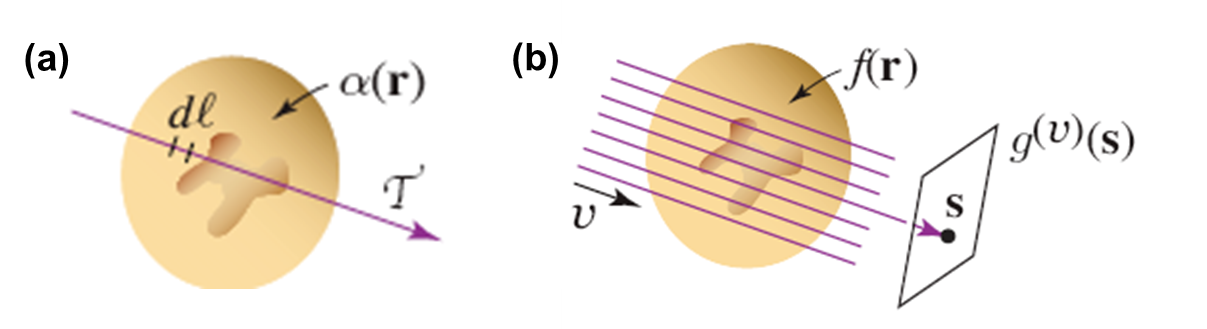

**ILL. 2.1 ***(a) Pencil beam attenuated by the object along the ray path and (b) ray transmission as a projection of a 3D object on a 2D image.*

### 2.2 CT measurment model: Radon transform

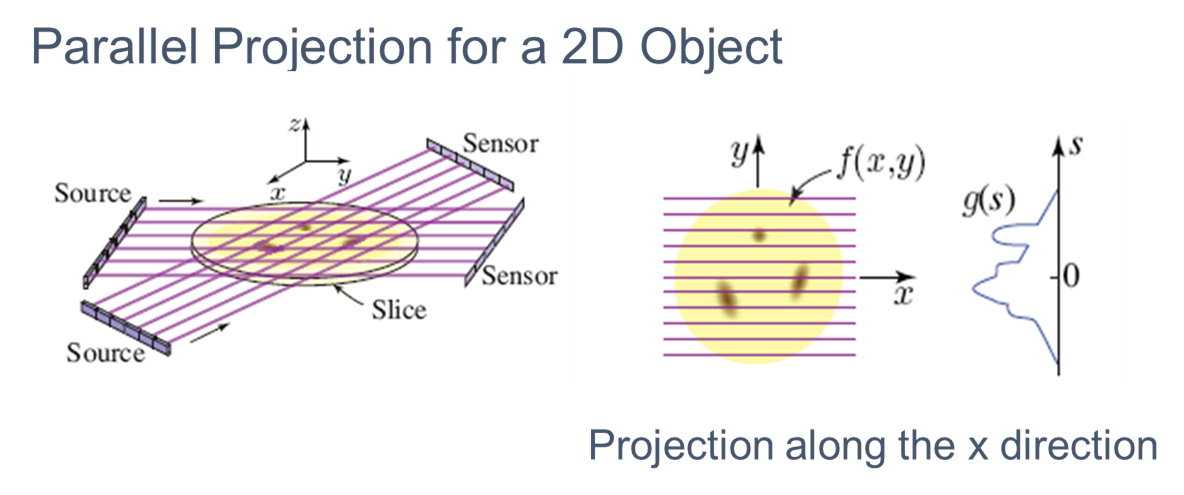

**ILL. 2.2 ***Tomography measures multiple projections from different angles*


$$g\left(s\right)=\int^{\infty } \int_{-\infty } \delta \left(y-s\right)f\left(x,y\right)\;\textrm{dx}\;\textrm{dy}=\int_{-\infty }^{\infty } f\left(x,s\right)\textrm{dx}$$


Similarly, for projection along the $y$ direction, $g\left(s\right)=\int_{-\infty }^{\infty } f\left(s,y\right)\;\textrm{dy}$

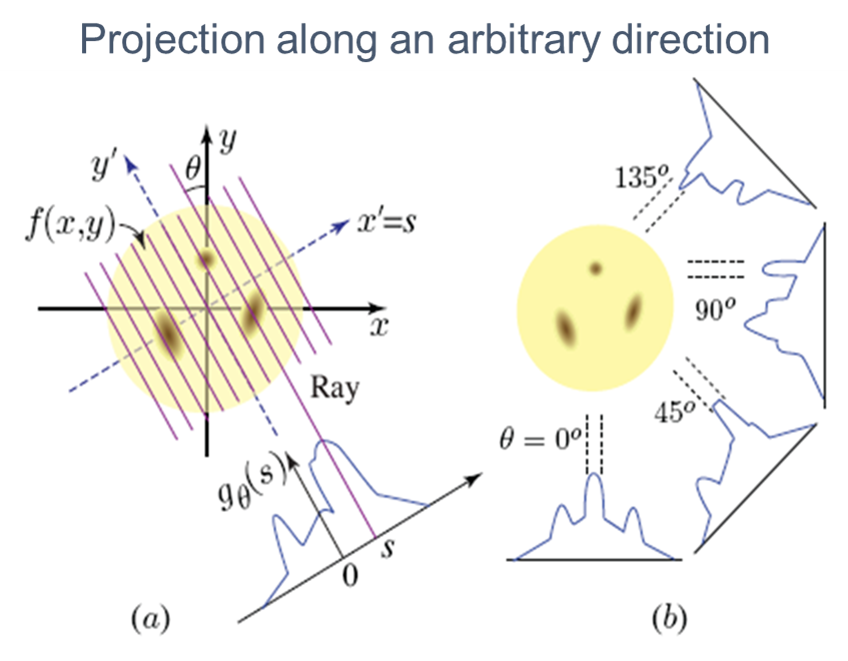

**ILL 2.3 ***(a) Projection of the 2D distribution *$f\left(x,y\right)$* along a direction making an angle *$\theta$* with the *$y$* axis produces a 1D function *$g_{\theta } \left(s\right)$*of the distance *$s$* from the origin. (b) Projections at four angles: *$\theta =0\degree ,45\degree ,90\degree ,135\degree \ldotp$


$$g_{\theta } \left(s\right)=\int^{\infty } \int_{-\infty } \delta \left(x\;\cos \theta +y\;\sin \theta -s\right)f\left(x,y\right)\;\textrm{dx}\;\textrm{dy}$$


The projection equation may be written as a single integral by using a coordinate system $\left(s,u\right)$ aligned with the ray. The $\left(x,y\right)\to \left(s,u\right)$ coordinate rotation:


$$s=x\;\cos \theta +y\;\sin \theta$$
        
$$x=s\;\cos \theta -u\;\sin \theta$$



$$u=-x\;\sin \theta +y\;\cos \theta$$
    
$$y=s\;\sin \theta +u\;\cos \theta$$


Projection Equation:


$$g_{\theta } \left(s\right)=\int_{-\infty }^{\infty } f\left(s\;\cos \theta -u\;\sin \theta ,\;s\;\sin \theta +u\;\cos \theta \right)\;\textrm{du}$$


The objective of ray tomography is to invert this equation, i.e., to determine the object $f\left(x,y\right)$ from the projections $g_{\theta } \left(s\right)$ at all angles $\theta$. Essentially the transformation $f\left(x,y\right)\to g\left(\theta ,s\right)$, is called the radon transform. 

***Example 2.1 ***

Radon transform of a phantom in matlab using radon: MATLAB equation `g=radon(f) `performs a discretized form of the Radon transform, where `f `and` g `are matrices representing discretized versions of $f\left(x,y\right)$ and $g\left(x,y\right)$, respectively.

`iradon `performs the inversion of the radon transform, which we will discuss in more detail on the reconstructions.

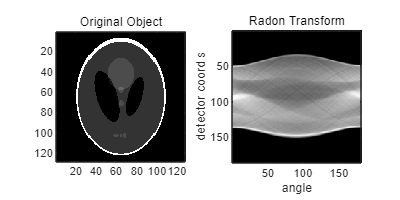

%% Projection/Radon Transform
nx=128;
F=phantom(nx);
figure()
subplot(121)
imagesc(F)
subtitle('Original Object')
axis image;
colormap gray
% Radon Transform
theta=0:1:180;
G=radon(F, theta);
% Display Radon Transform
subplot(122)
imagesc(G)
subtitle('Radon Transform')
xlabel('angle'); ylabel('detector coord s');
axis image;
colormap(gray)
set(gcf,'Position', [100 100 400 200])

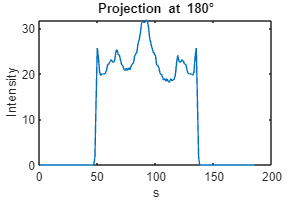

figure()
set(gcf,'Position', [100 100 300 200])
for kk =1:5:181
    plot(G(:,kk))
    title(['Projection at ', num2str(theta(kk)),'\circ'])
    xlabel('s')
    ylabel('Intensity')
    pause(0.5)
end

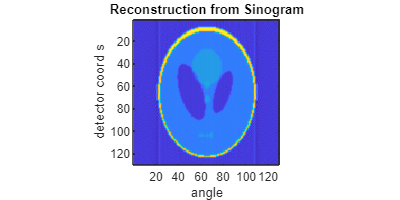

%% Reconstruction, just an overview
f_hat=iradon(G, theta);
figure()
imagesc(f_hat)
set(gcf,'Position', [100 100 400 200])
title('Reconstruction from Sinogram')
xlabel('angle'); ylabel('detector coord s');
axis image;

**Properties of the Radon Transform. ** Some of the principal properties of the Radon transform are: 

- The Radon transform is linear i.e., $\Re \left(a_1 f_1 +a_2 f_2 \right)=a_1 \Re f_1 +a_2 \Re_2 f_2$, where $f_1$ and $f_2$ are functions and $a_1$ and $a_2$ are constraints.

- The Radon transform is rotationally invariant, i.e, if $g=\Re f$ and $f_{\phi }$ equals $f$ rotated by an angle $\phi$, then the Radon transform $g_{\phi } =\Re f_{\phi }$ of $f_{\phi }$ equals $g$ rotated by the same angle $\phi$.

The Radon transform of a point will generate a sinusoidal trace. The original point's location, and intensity are encoded in the amplitude, phase, and the pixel values of the curve. Therefore, the Radon transform $g$ is also called the sinogram. 

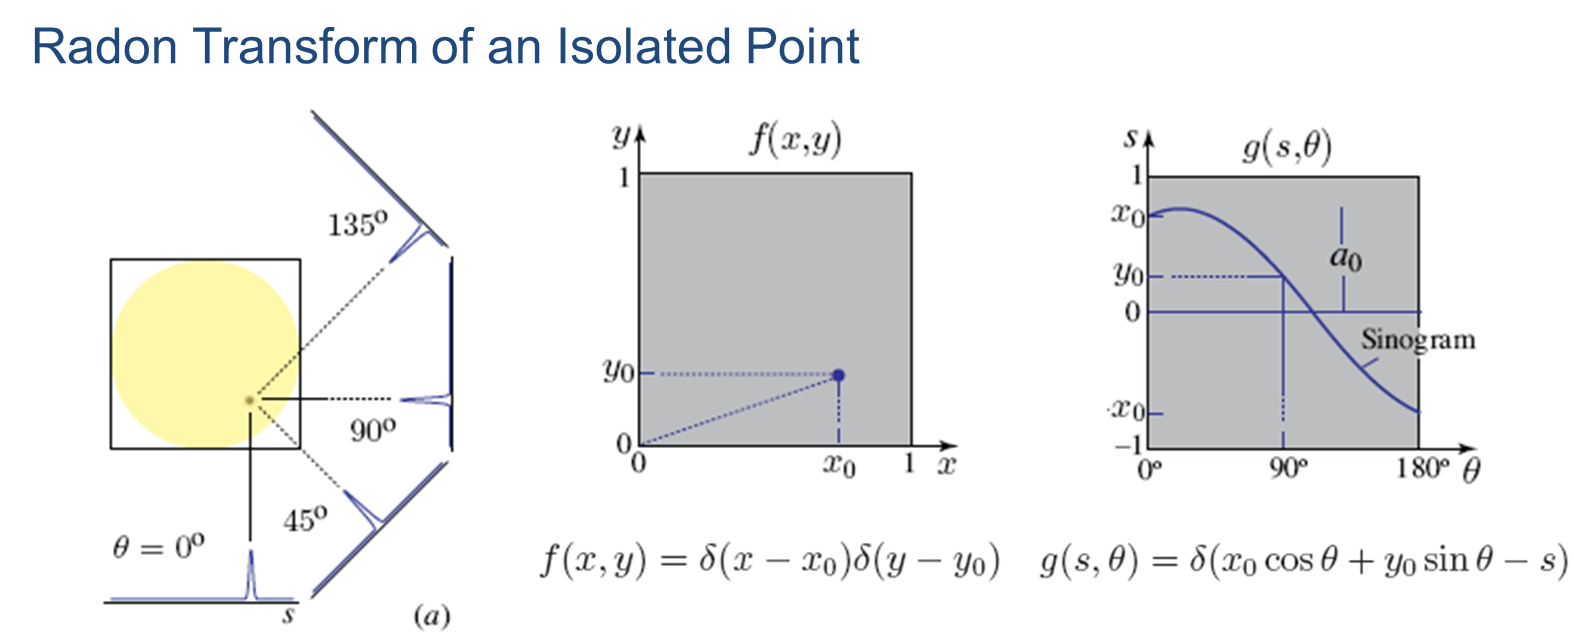

**ILL. 2.4 ***Sinogram of an isolated point*

***Example 2.2 ***

Sinogram of points: The super-position of the sine curves demonstrates the linearity of the Radon transform.

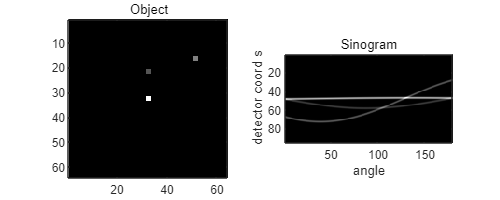

%% Point object Sinogram
nx = 64;
F2=zeros(nx);
% Use drop down menu to add points
point = "3 Points";
if point == '1 Point'
    F2(nx/2+(0:1),nx/2+(0:1))=1; % point 1
elseif point == '2 Points'
    F2(nx/2+(0:1),nx/2+(0:1))=1;
    F2(round(nx/3)+(0:1),round(nx/2)+(0:1))=1/3; % point 2
elseif point == '3 Points'
    F2(nx/2+(0:1),nx/2+(0:1))=1;
    F2(round(nx/3)+(0:1),round(nx/2)+(0:1))=1/3; % point 2
    F2(round(nx/4)+(0:1),round(nx*4/5)+(0:1))=1/2; % point 3
end

figure()
subplot(121) 
imagesc(F2) %display object
subtitle('Object')
axis image;
theta=1:180;
G2=radon(F2, theta);
subplot(122)
imagesc(G2) %display sinogram
subtitle('Sinogram')
xlabel('angle'); ylabel('detector coord s');
axis image;
colormap(gray)
set(gcf,'Position', [100 100 500 200])

### 2.3 Reconstruction: Projection-Slice Theroem

The Projection-Slice Theorem states that if you take the 2D Fourier transform of the original 2D function and then extract a slice from this transform along a radial line corresponding to a specific frequency, the 1D Fourier transform of your original 1D projection will match this slice. In other words,


$$G_{\theta } \left(k_s \right)=F\left(k_s \cos \theta ,k_s \sin \theta \right)$$


$\prime F^{\prime }$ here is the Fourier transform and $k_s$ is the 1D frequency coordinate along the projection direction.

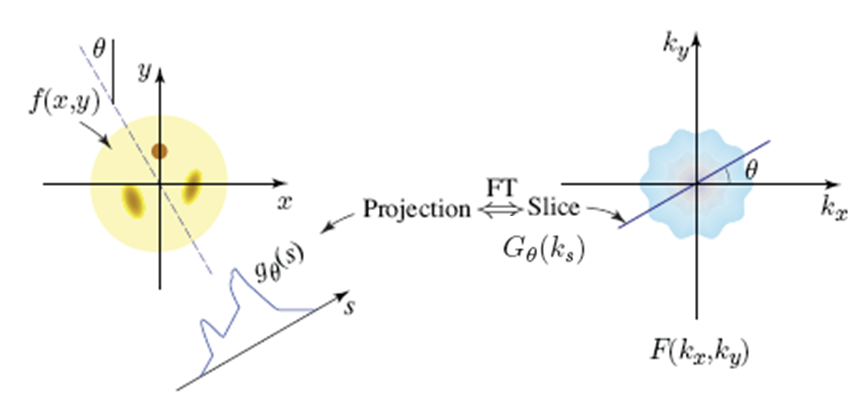

**ILL. 2.5 ***Projection-Slice Theroem*

**Proof of the P-S Theroem. ** The P-S theorem may be easily proved in the special case of projection along the $y$ axis ($\left.\theta =0\right)$. In this case, 

$g_0 \left(x\right)=\int_{-\infty }^{\infty } f\left(x,y\right)\textrm{dy}$. **(11.1)**

The 2D Fourier transform of $f\left(x,y\right)$ evaluated at $k_y =0$ is

$F\left(k_x ,0\right)=\int^{\infty } \int_{-\infty } f\left(x,y\right)e^{{\textrm{jk}}_x x} \textrm{dxdy}=\int_{-\infty }^{\infty } e^{{\textrm{jk}}_x x} \int_{-\infty }^{\infty } f\left(x,y\right)\textrm{dydx}$  ** (11.2)**

Substituting from (11.1) into (11.2), we obtain

$F\left(k_x ,0\right)=\int_{-\infty }^{\infty } g_0 \left(x\right)e^{{\textrm{jk}}_x x} \textrm{dx}=G_0 \left(k_x \right)$. **(11.3)**

This proves the P-S theorem for the special case $\theta =0$. Since rotation of a function $f\left(x,y\right)$ by an angle $\theta$ rotates its Fourier transform by the same angle, the P-S theorem must apply for all angles.

***Example 2.3 ***

Projection-slice theorem visualization: The object is a 2D pattern with only one spatial frequency component. According to P-S theorem, there should be only one projection (the one that orthogonal to the frequency component) that contains this frequency. Feel free to change the amplitude $\left(k_s \right)$ and direction $\left(\alpha \right)$ in the code to observe.

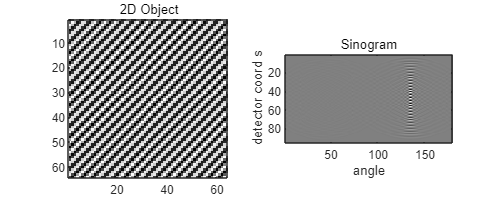

%% Sinusoidal function, P-S theorem
nx = 64;
x=1:nx;
y=1:nx;
[X,Y]=ndgrid(x,y);
alpha_max = pi;
alpha_step = pi/4;
ks_step = pi/3;
ks_min = pi/3;
% adjust the direction and/or frequency amplitude
alpha = 0.7853981633974483; % direction
ks = 2.0943951023931953; % frequency amplitude
kx=ks*cos(alpha);
ky=ks*sin(alpha);
F3=cos(kx.*X+ky.*Y);
figure()
subplot(121)
imagesc(F3)
subtitle('2D Object')
axis image;

theta=1:180;
G3=radon(F3, theta);
subplot(122)
imagesc(G3)
subtitle('Sinogram')
xlabel('angle'); ylabel('detector coord s');
axis image;
set(gcf,'Position', [100 100 500 200])
colormap(gray)

## 3. Numerical CT reconstruction

### 3.1 Sampling and filtered backprojection

If projections at all angles are measured, slices covering the entire $\left(k_x ,k_y \right)$ plane may be determined. A 2D inverse Fourier transform reproduces $f\left(x,y\right)$.

Since in real systems the number of projections is finite, the slices lie on a polar grid and must be interpolated into a rectangular grid before the inverse Fourier transform is computed using numerical techniques. Clearly, the sampling density is poor at high spatial frequencies. The sampling density is inversely proportional to the norm of the frequency, i.e., $k_p$, shown in ILL. 3.1.

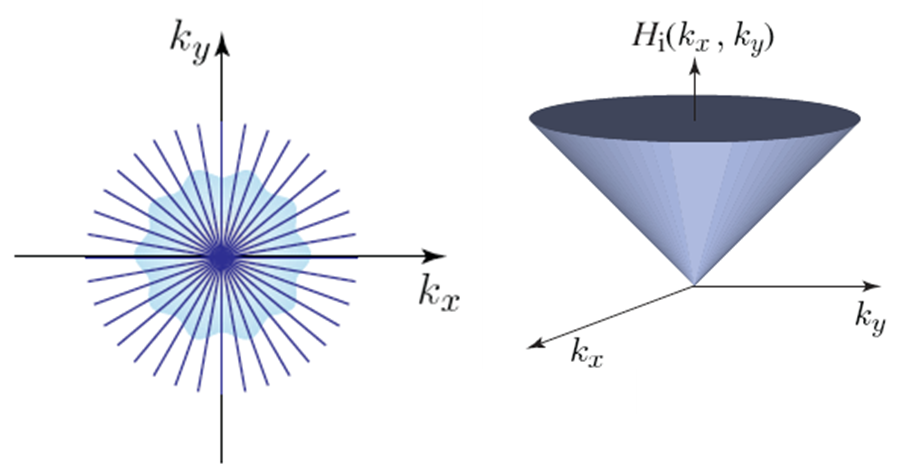

**ILL. 3.1 ***(a) Illustration of the sampling in the frequency domain; (b) the backprojection filter compensating the sampling density.*

To compensate the sampling density, a frequency domain filter $\left(H_i \right)$ will need to be applied to the sinogram.

Backprojection followed by an inverse filter $H_i =\frac{1}{H_e }$


$$H_i \left(k_x ,k_y \right)=\sqrt{k_x^2 +k_y^2 }=k_{\rho }$$


If $g=\Re f$ is the Radon transform of $f$ and $f_b =Bg$ is the backprojection of $g$ then the backprojection is a filtered version of the original function


$$f_b \left(x,y\right)=f\left(x,y\right)\otimes h_e \left(x,y\right)$$


Where $h_e$ is the sampling filter in the spatial domain i.e., $H_e \overset{\textrm{IFT}}{\to} h_e$, and 


$$H_e \left(k_x ,k_y \right)=\frac{2\pi }{\sqrt{k_x^2 +k_y^2 }}=\frac{2\pi }{k_{\rho } }$$


The straightforward compensation we showed here is known as the Ram-Lak filter. A truncated version of $H_i$ is often used, such as the Shepp-Logan filter.

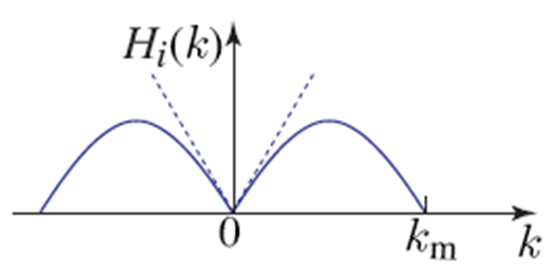

**ILL. 3.2 ***Shepp-Logan filter is a type of truncated version*

***Example 2.4 ***

Backprojection filtering and comparison: Compare the three type of filtering, 'Ram-Lak', 'Shepp-Logan', and 'None'. See what the filter in the spatial domain looks like, and also compare the reconstructed images.

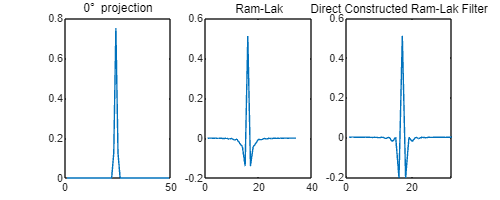

%% Filtered back projection
% single point iradon, showing the filter
nx=32;
F=zeros(nx);
F(round(nx/2), round(nx/2)-1)=1; % a point at the center
theta = 0;
G=radon(F, theta); % generate projection

figure()
subplot(131)
plot(G) % plot projection
subtitle('0\circ projection')

i_filter = "Ram-Lak"; % select filter: "None", "Ram-Lak", or "Shepp-Logan"
F_hat = iradon(G, theta,"linear",i_filter); % just reconstruct
subplot(132)
plot(F_hat(round(nx/2),:)) %plot filter
subtitle(i_filter);

% Compare with analytically constructed frequency domain Ram-Lak filter
h_f = linspace(-1,1,size(G,1));
h_f = abs(h_f); %filter in frequency domain
H = fftshift(ifft(fftshift(h_f)));
H_t = H(round(end/2-nx/2):round(end/2+nx/2)-1);% truncate for comparison
subplot(133)
plot(real(H_t)) % direct constructed Ram-Lak filter
subtitle('Direct Constructed Ram-Lak Filter')
set(gcf,'Position', [100 100 500 200])

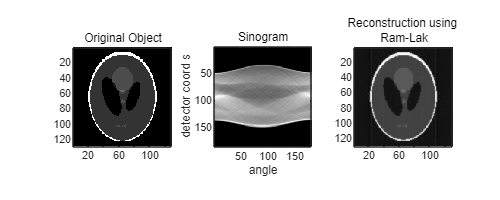

% show and compare the filtered backprojected reconstruction
nx=128;
F=phantom(nx);

figure()
subplot(131)
imagesc(F)
subtitle('Original Object')
axis image;
colormap gray
theta=0:1:180;
G=radon(F, theta); %radon tranform

subplot(132)
imagesc(G)
subtitle('Sinogram')
xlabel('angle'); ylabel('detector coord s');
axis image;
colormap(gray)

F_hat=iradon(G, theta, "linear", i_filter); % reconstruction

subplot(133)
imagesc(F_hat)
subtitle(['Reconstruction using ',i_filter])
axis image;
colormap(gray)
set(gcf,'Position', [100 100 500 200])

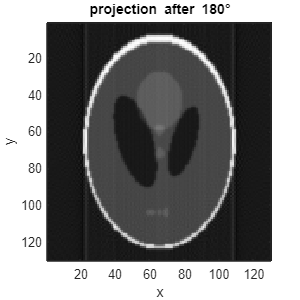

%% Spatial vs frequency domain of the accumulation of the projection
figure()
set(gcf,'Position', [100 100 300 300])
F_hat=iradon(G(:,1),theta(1));

for kk =2:1:length(theta)
    F_hat = F_hat+iradon([G(:,kk) G(:,kk)],[theta(kk) theta(kk)])/2;
    imagesc(F_hat)
    title(['projection after ', num2str(theta(kk)),'\circ'])
    xlabel('x')
    ylabel('y')
    colormap(gray)
    pause(0.1)
end

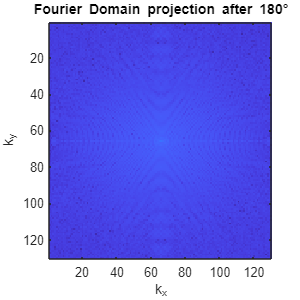

%Fourier Domain Projection
figure()
set(gcf,'Position', [100 100 300 300])
F_hat=iradon(G(:,1),theta(1));
for kk =2:1:181
    F_hat = F_hat+iradon([G(:,kk) G(:,kk)],[theta(kk) theta(kk)])/2;
    FF_hat = fftshift(fft2(F_hat));
    image(log(abs(FF_hat))*5)
    title(['Fourier Domain projection after ', num2str(theta(kk)),'\circ'])
    xlabel('k_{x}')
    ylabel('k_{y}')
    pause(0.1)
end

### **3.2 Algebraic Reconstruction Technique (ART)**

The Algebraic Reconstruction Technique (ART) is a method used for reconstructing an image from its projections, such as in computed tomography (CT). ART can be considered as an iterative solver of a system of linear equations $\textrm{Ax}=b$, where:

$A$ is a sparse $m\times n$ matrix whose values represent the relative contribution of each output pixel to a different points in the sinogram ($m$ being the number of individual values in the sinogram, and $n$ being the number of output pixels);

$x$ represents the pixels in the generated (output) image, arranged as a vector, and $b$ is a vector representing the sinogram. Each projection (row) in the sinogram is made up of a number of discrete values, arranged along the transverse axis. $b$ is made up of all of these values, from each of the individual projections.

Calculating the length of the segment of the ray


$$d_i =\sqrt{{\left(x_{i+1} -x_i \right)}^2 +{\left(y_{i+1} -y_i \right)}^2 }$$


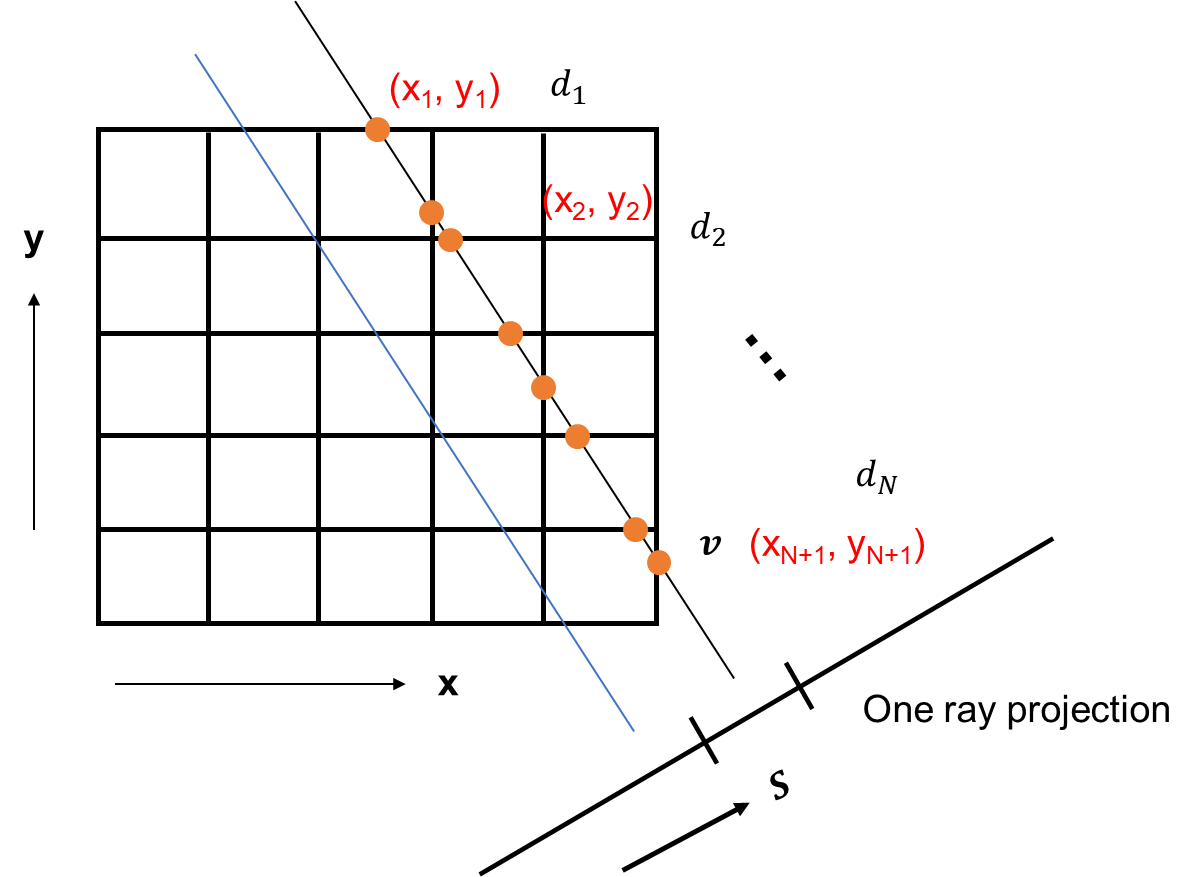

**ILL. 3.3 ***Building the forward matrix by calculating the length of the intersected segment of the ray and the pixels (voxels).*

**Construction of the forward model**

To calculate the forward matrix for the Algebraic Reconstruction Technique (ART) in CT:

- Discretize the image into a grid of pixels (2D) or voxels (3D). Assume you have $N$ pixels in total. 

- Determine the number of projection angles and the number of rays for each angle. Assume you have $M$rays in total. The forward matrix will have a size of $M\times N$. Initialize all elements to zero.

- For each ray (i.e., for each row in the matrix): (a) Determine the path that the ray takes through the grid. (b) For each pixel that the ray intersects: Calculate the length of the segment of the ray that lies within the pixel. This length is proportional to the contribution of the pixel to the ray's measurement. Set the matrix entry corresponding to that ray and pixel to the computed length.

## 4. Application of CT

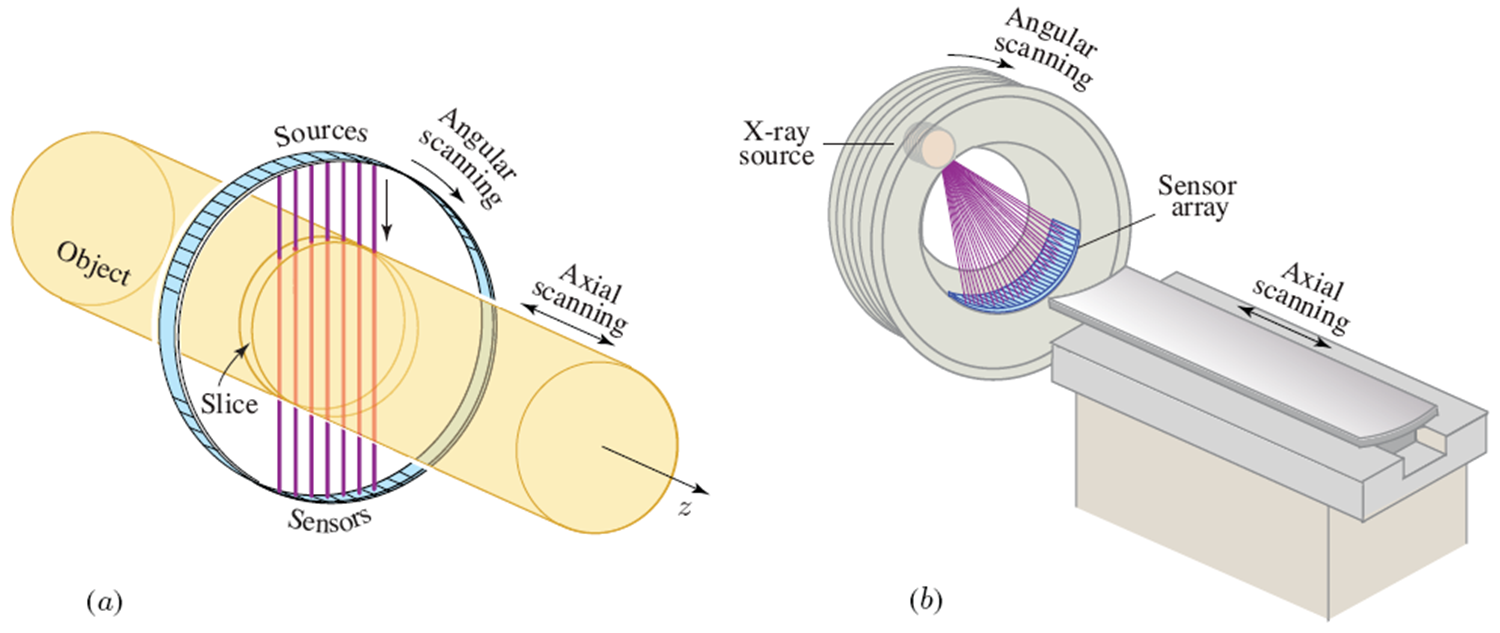

**ILL. 4.1 ***CAT is a combination of axial slicing, which is a form of localized probing, and 2D ray tomography in the transverse. (a) Parallel rays emitted by an array of X-ray sources are transmitted through each slice of the object and detected by array detectors. (b) Fan-shaped rays used in a medical CT scanner.*

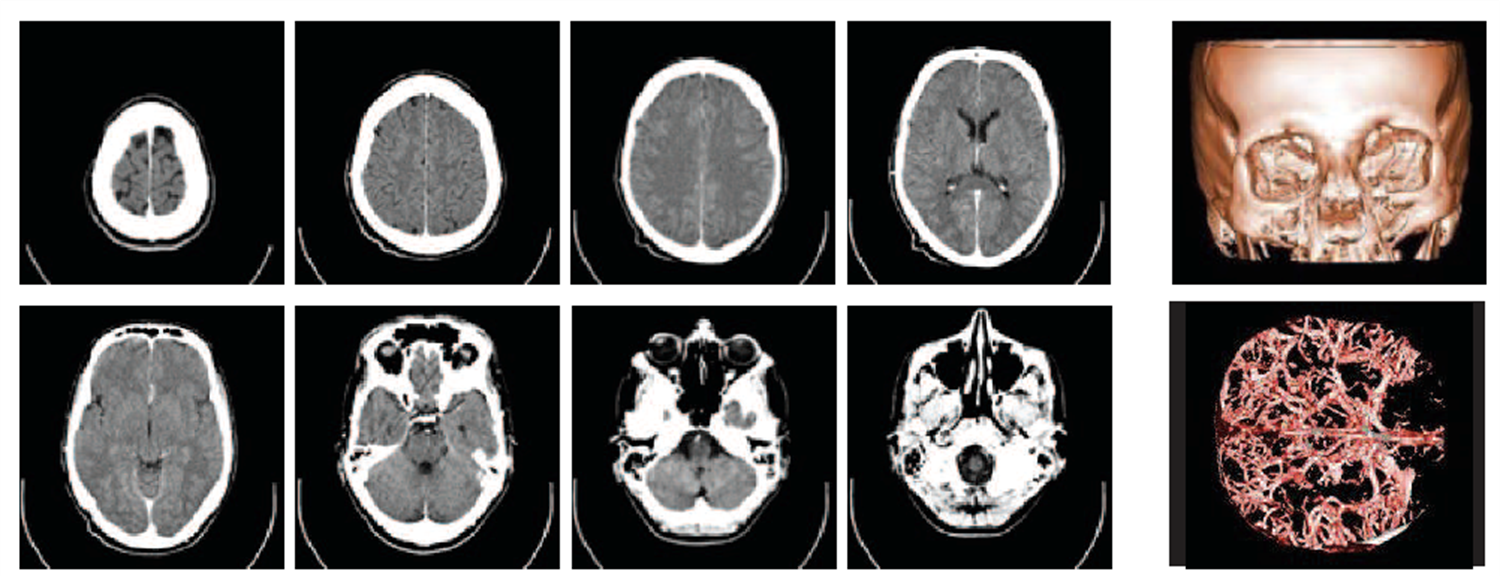

**ILL. 4.2 ***Eight slices of a cranial X-ray CT scan (from top to the base of the skull). An intravenous contrast medium was used. Top right: a volume rendering shows the high-density bones. Bottom right: the bone is removed using an image processing segmentation tool to show the previously concealed vessels. (Public domain images, courtesy of Mikael Haggstron, Radiology, Uppsala University Hospital; wikipedia.org/wiki/X-ray_computed_tomography.)*

In conventional mammography, two low-dose X-ray images of each breast are usually taken: a top-to-bottom projection and a side-to-side projection. Breast cancer lesions, which are denser than the surrounding healthy fibroglandular breast tissue, appear as irregular white areas. These two 2D projections, however, may not show lesions obstructed by dense healthy fibroglandular tissue in the projection direction.

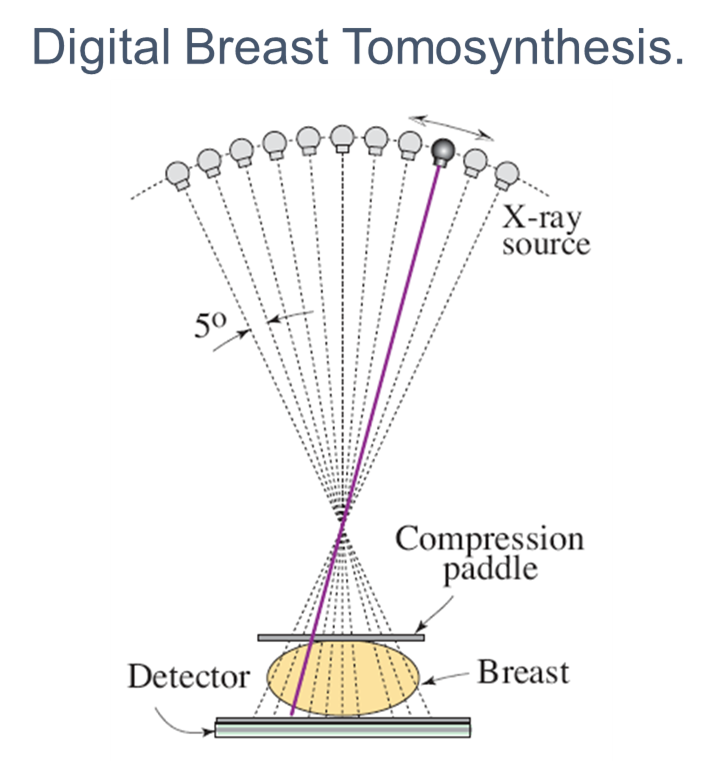

**ILL. 4.3 ***Tomosynthesis*

DBT uses multiple low-dose X-ray projections of each breast from many angles, typically 11 different angles covering a span of 40$\degree$, as shown in ILL. 4.3. The breast is positioned as in a conventional mammogram (but only a little pressure is applied) and the images are taken with an X-ray tube moving in an arc around the breast. The projections are processed using ray tomography techniques, such as filtered backprojection, and a 3D image of the breast is computed. The image is usually displayed in the form of a series of slices, or rotated in space for a more careful examination, or viewed in 3D to bring structures into relief. It is believed that this new breast imaging technique will make breast cancer easier to detect.